Load Images

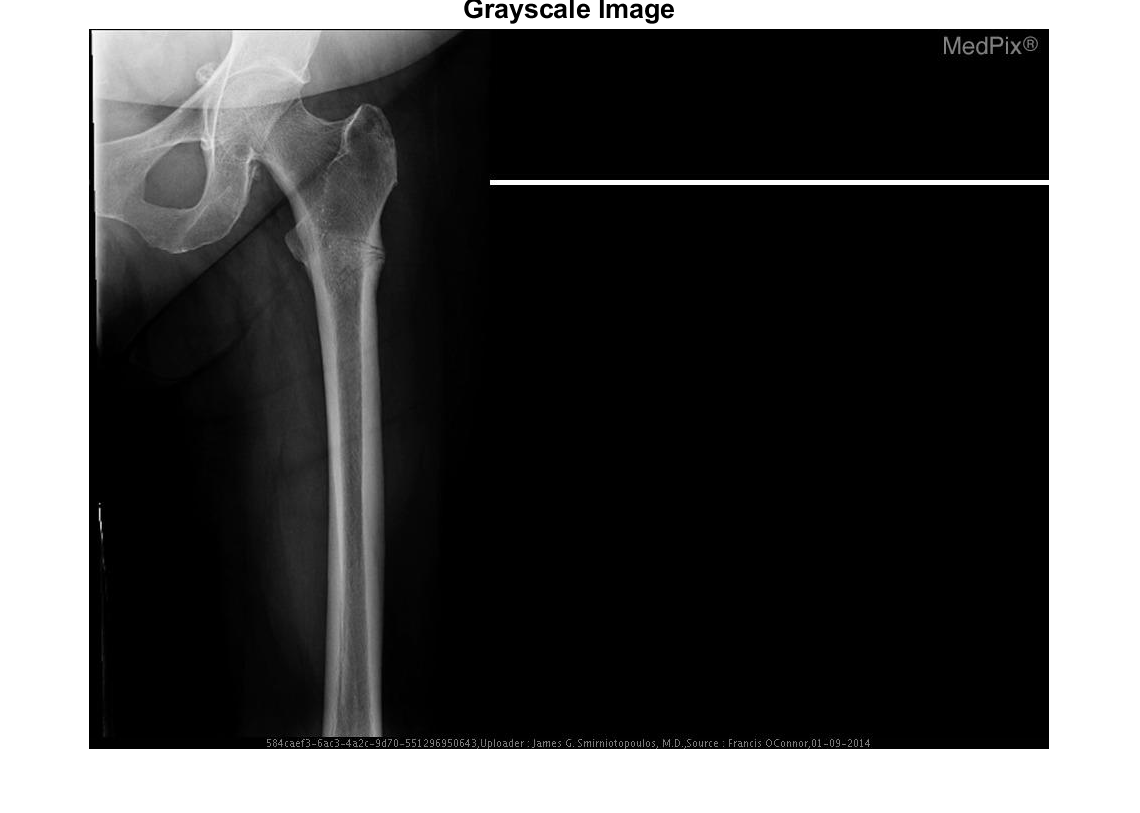

I = imread('synpic59769.jpg');
[q,w,e] = size(I);
if e ~= 0
    Ig = rgb2gray(I);
end
Brightness = 1;
Ig = Ig*Brightness;
imshow(Ig); title('Grayscale Image','FontSize',20);

Create Image filter

h = fspecial('average', 5);

Apply Image Filter

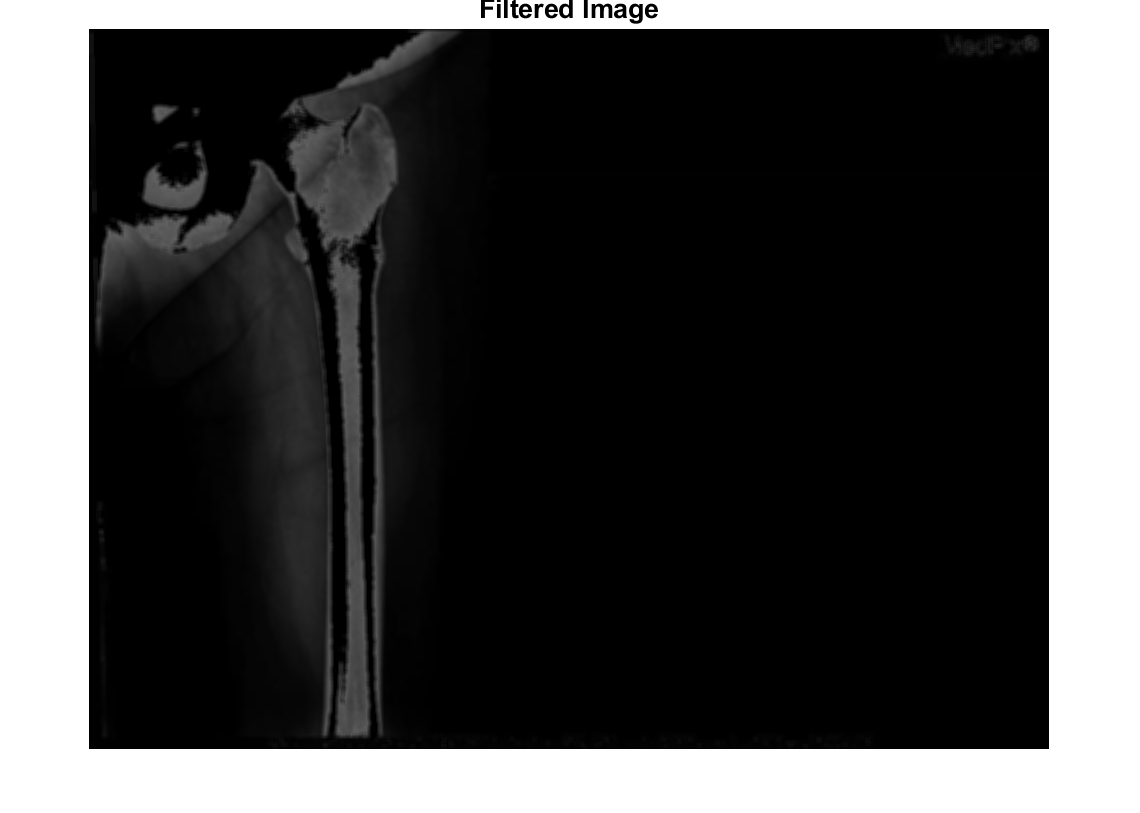

Ig(find(Ig>100)) = 0;
Ic = imfilter(Ig, h);
imshow(Ic); title('Filtered Image','FontSize',20);

Apply Threshholding

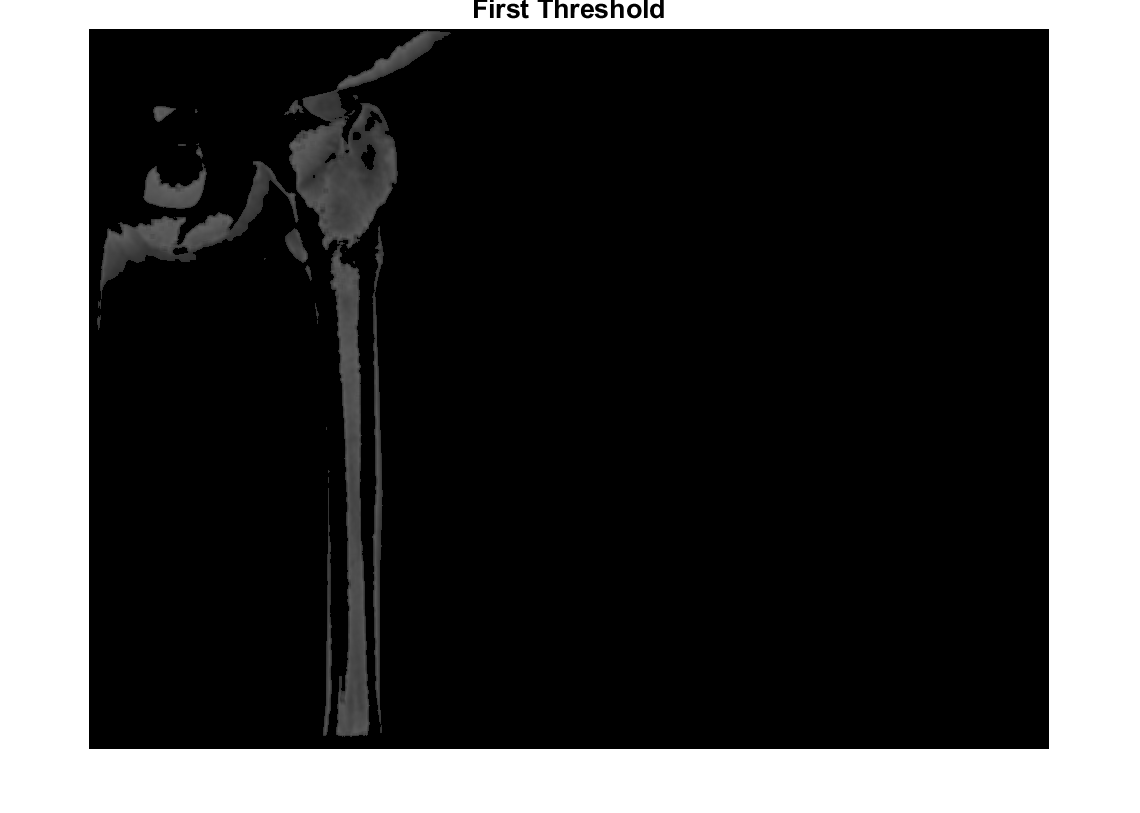

Ic1 = Ic;
Ic1(find(Ic1<50)) = 0;
imshow(Ic1); 
title('First Threshold','FontSize',20);

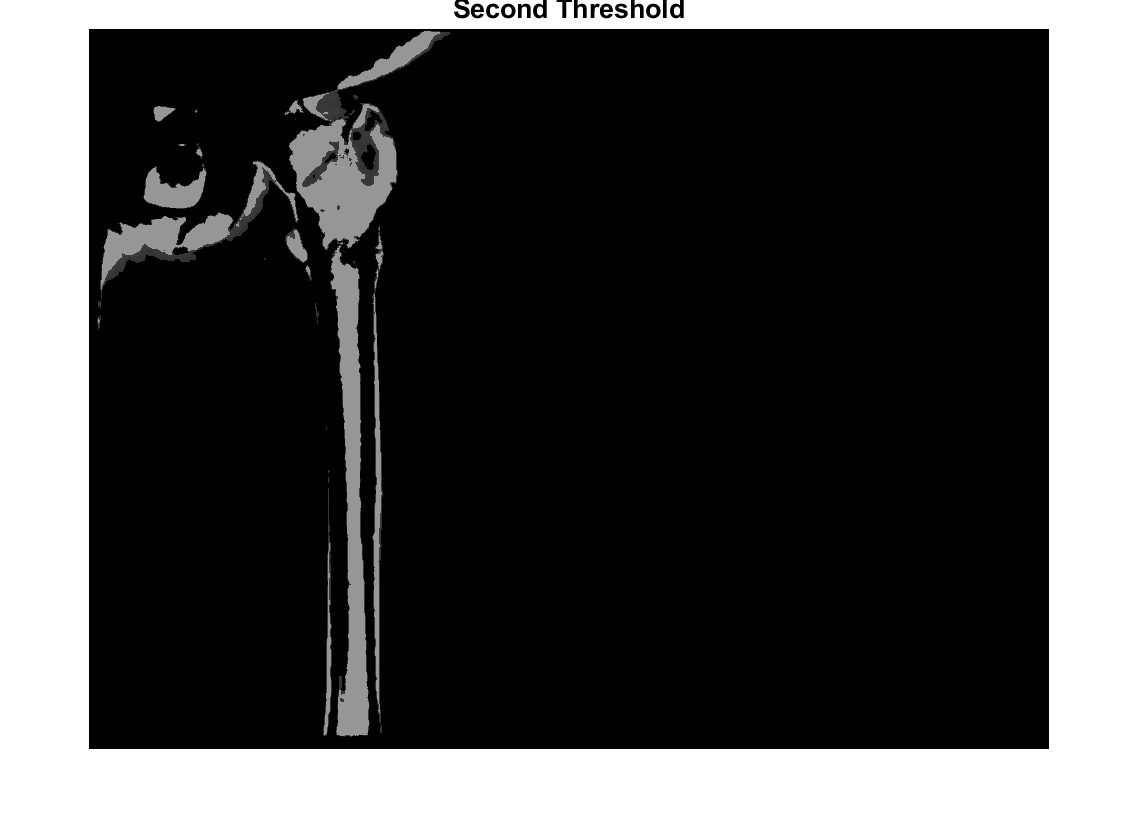

[i, j] = size(Ic1);
Ic2 = Ic1;
for x = 1:i
    for y = 1:j
        if Ic2(x, y) > 60 && Ic2(x, y) < 100
            Ic2(x, y) = 150;
        end
    end
end
imshow(Ic2); 
title('Second Threshold','FontSize',20);

Clear Border Artifacts

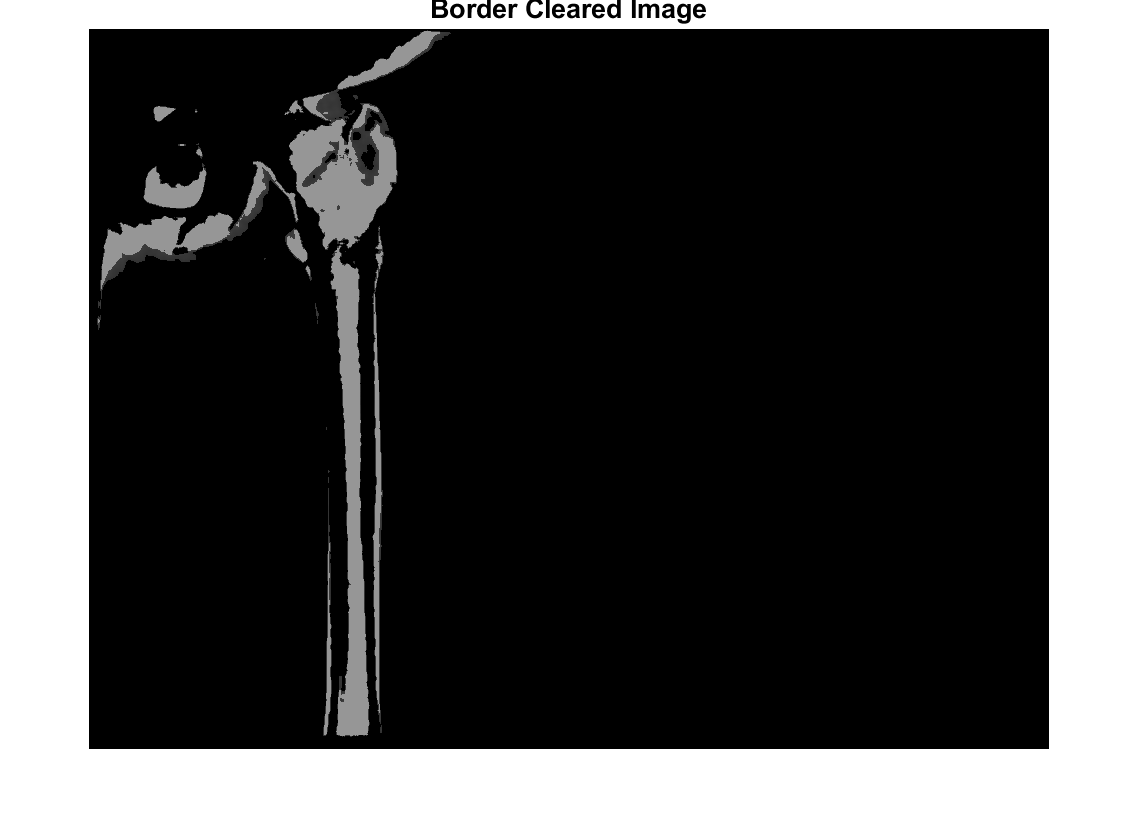

Ib = imclearborder(Ic2, 8);
imshow(Ib); 
title('Border Cleared Image','FontSize',20);

Clean Up Remaining Objects

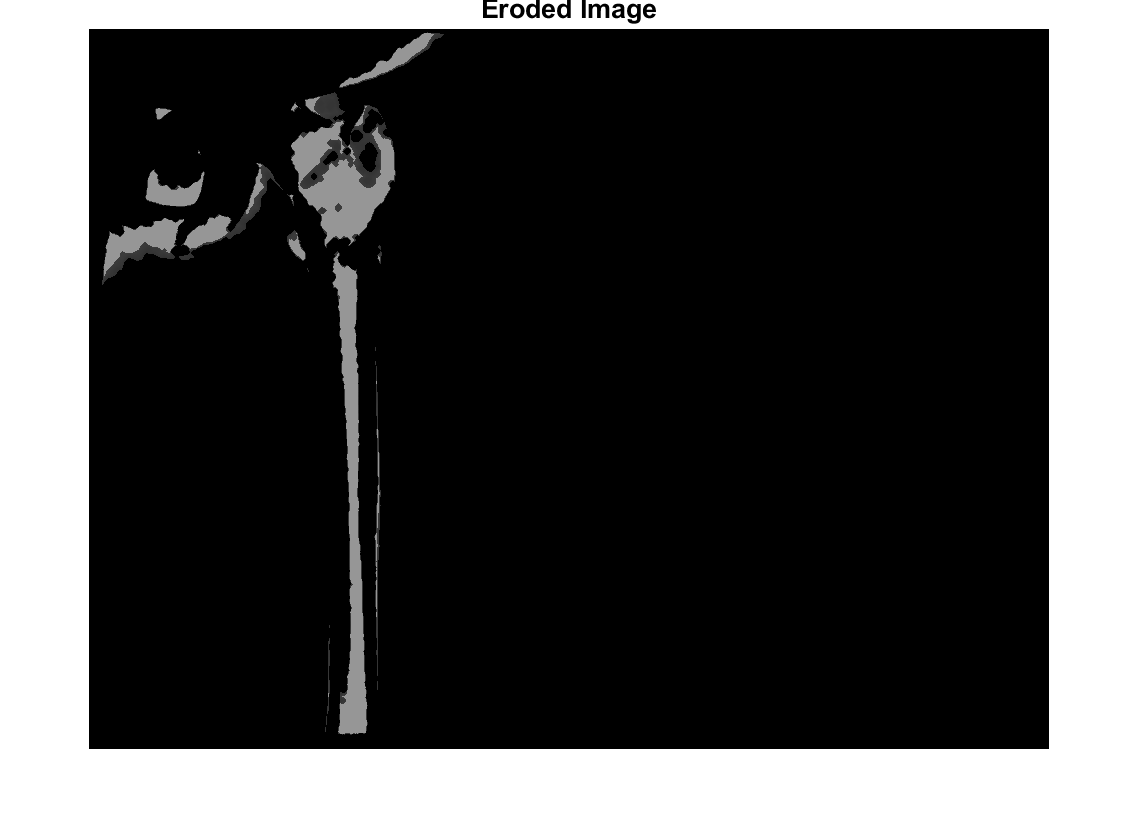

seD = strel('diamond', 2);
Ie = imerode(Ib, seD);
imshow(Ie); 
title('Eroded Image','FontSize',20);

Overlay Final image over Original

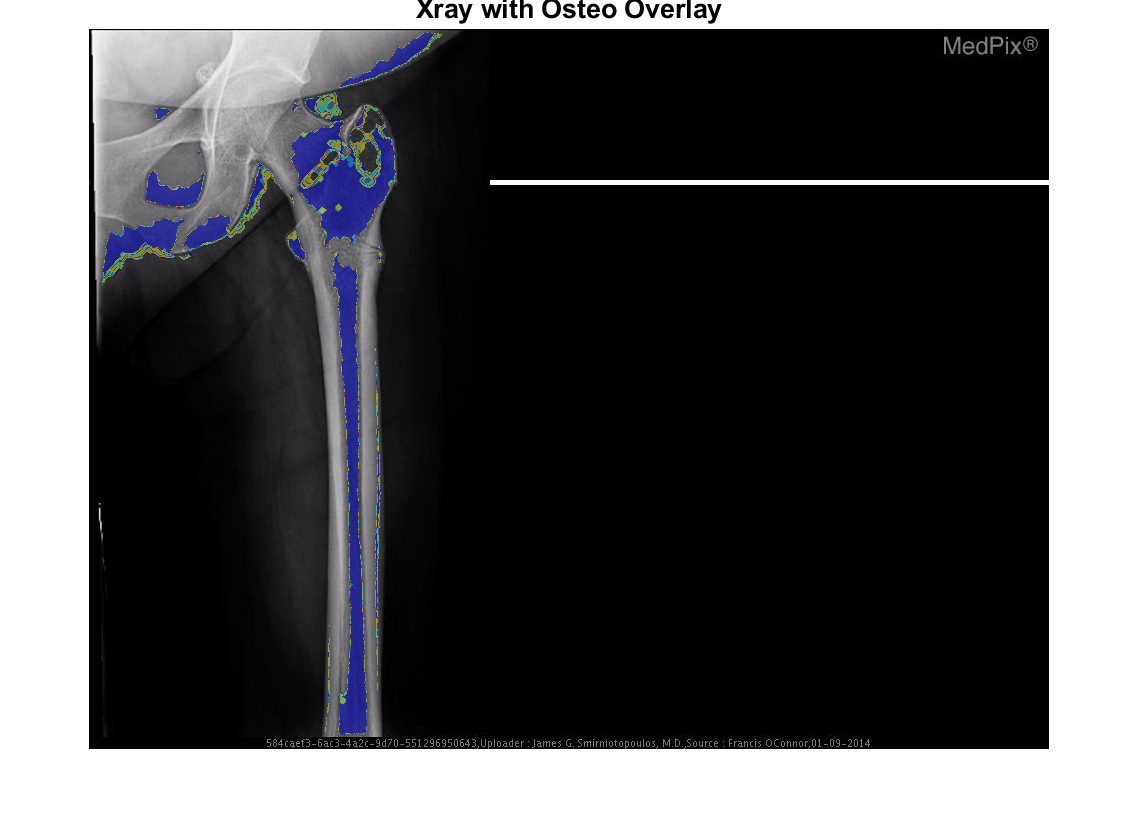

Io = labeloverlay(I, Ie);
imshow(Io);
title('Xray with Osteo Overlay','FontSize',20);

Determine Osteoporosis Percentage

Osteo = size(find(Ie>0));
Healthy = size(find(Ic1>0));
PercentOsteo = (Osteo/Healthy)*100;
display(PercentOsteo);

PercentOsteo = 72.9499